% Visual Crypto
clc;
clear;
close all;

% Read raw input(RGB secret)
raw_secret = imread("images/raw_secret.jpeg");

% Split into 3 channel(R,G,B)
R = raw_secret(:,:,1);
G = raw_secret(:,:,2);
B = raw_secret(:,:,3);

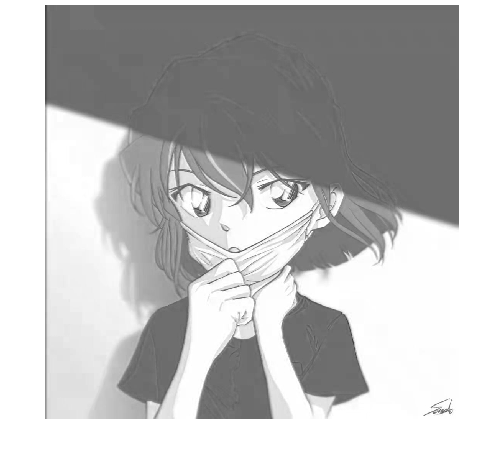

% Show gray image in R,G,B channel respectively
imshow(R)

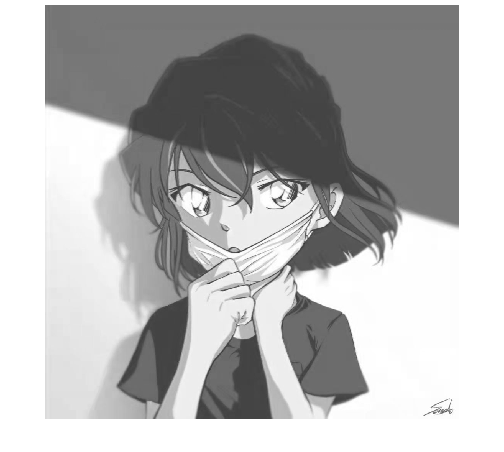

imshow(G)

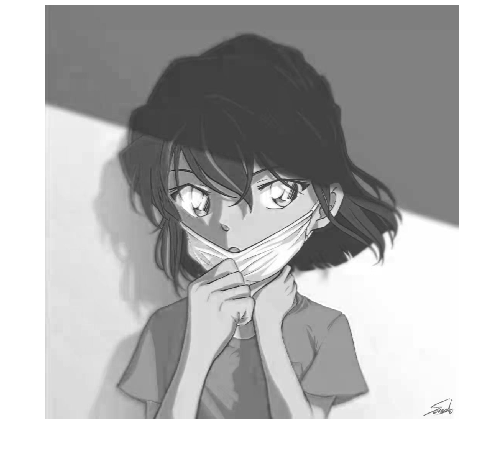

imshow(B)

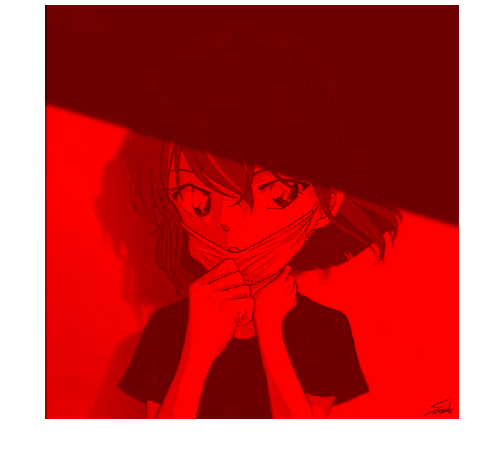

% Show image in R,G,B channel respectively
zero_image = uint8(zeros(size(raw_secret)));

% R
R_channel = zero_image;
R_channel(:,:,1) = R;
imshow(R_channel)

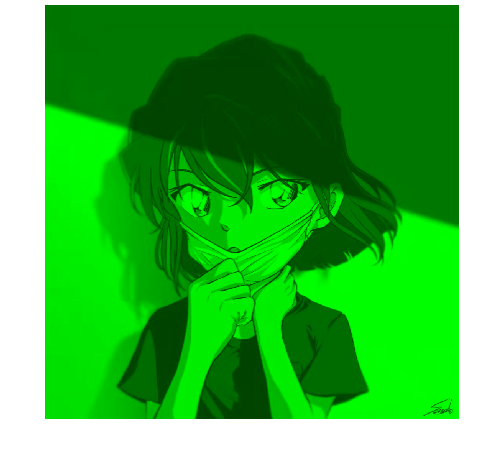


% G
G_channel = zero_image;
G_channel(:,:,2) = G;
imshow(G_channel)

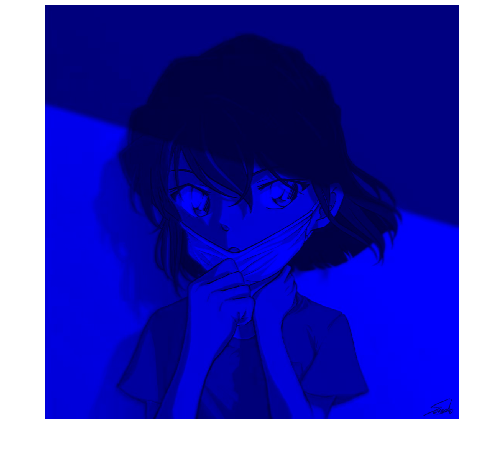


% B
B_channel = zero_image;
B_channel(:,:,3) = B;
imshow(B_channel)

% Image Binarization
% R_bin = imbinarize(R)

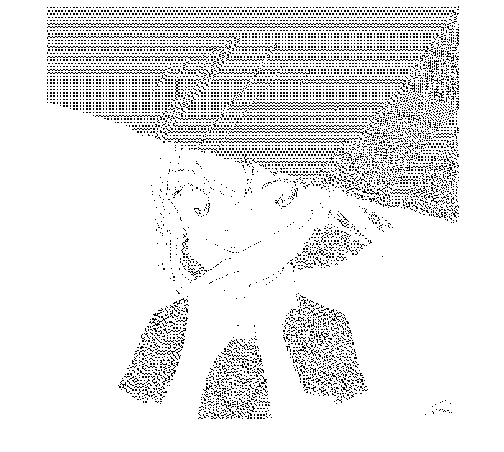

% Half-tone (Error Diffusion)
R_bin = halftone(R);
G_bin = halftone(G);
B_bin = halftone(B);

% Show halftoned image
imshow(R_bin)

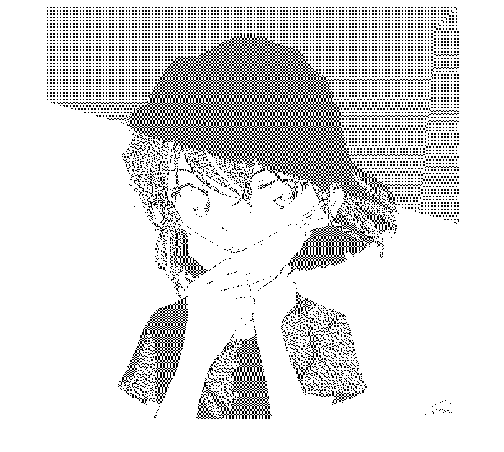

imshow(G_bin)

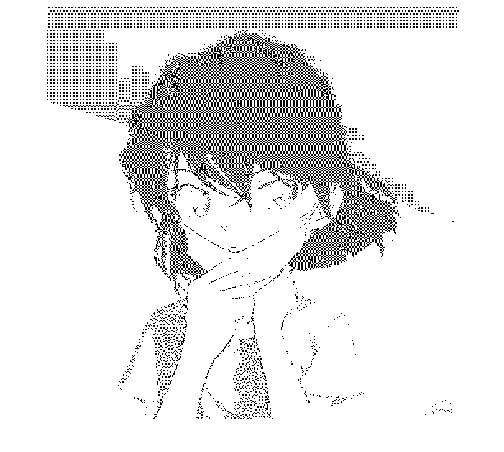

imshow(B_bin)

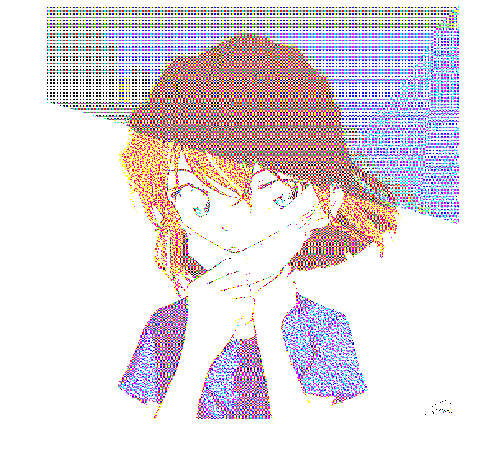


raw_bin(:,:,1) = R_bin;
raw_bin(:,:,2) = G_bin;
raw_bin(:,:,3) = B_bin;
imshow(raw_bin)

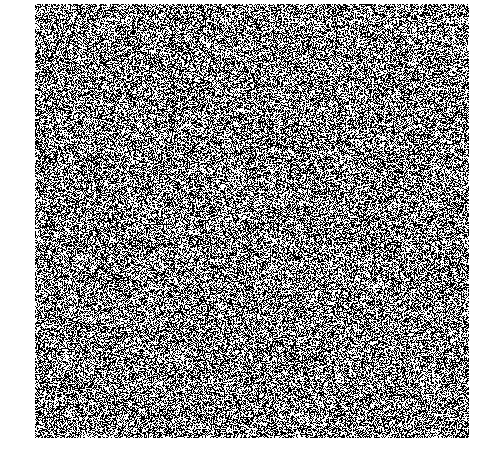

% Encrypt
[R_key1, R_key2] = crypto_enc(R_bin);
[G_key1, G_key2] = crypto_enc(G_bin);
[B_key1, B_key2] = crypto_enc(B_bin);

% Show Iamge
imshow(R_key1)

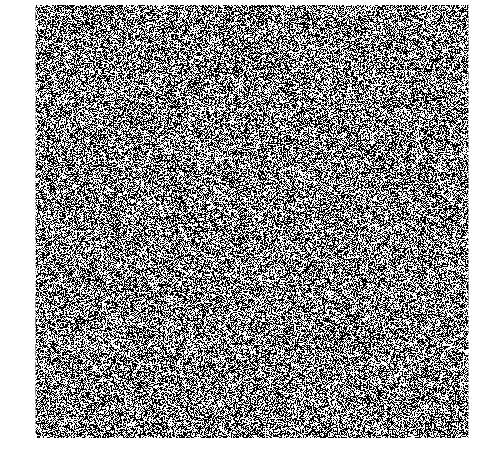

imshow(R_key2)

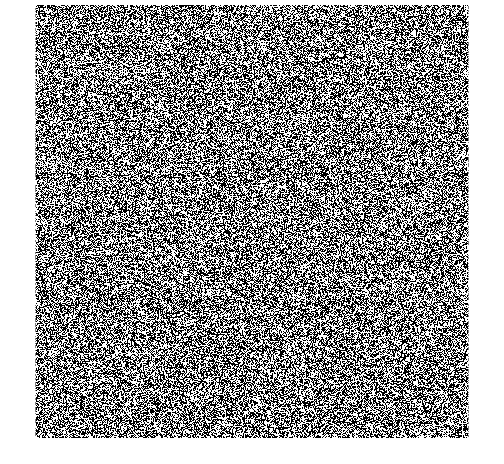

imshow(G_key1)

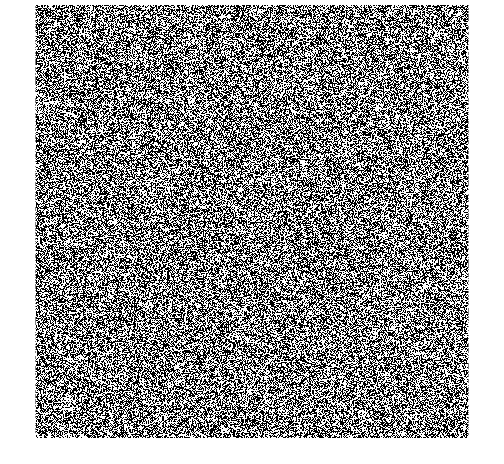

imshow(G_key2)

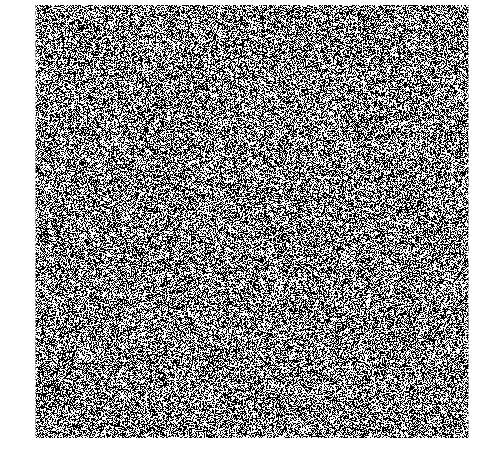

imshow(B_key1)

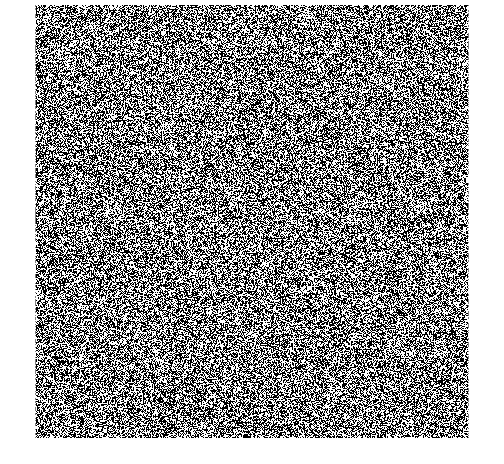

imshow(B_key2)

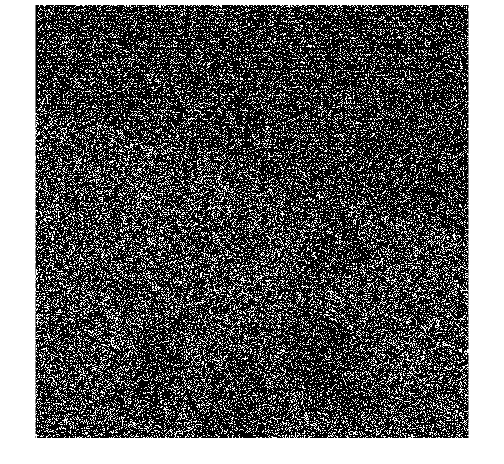

% Decrypt
[R_secret, R_secret_2x] = crypto_dec(R_key1, R_key2);
[G_secret, G_secret_2x] = crypto_dec(G_key1, G_key2);
[B_secret, B_secret_2x] = crypto_dec(B_key1, B_key2);

% Show Image
imshow(R_secret_2x)

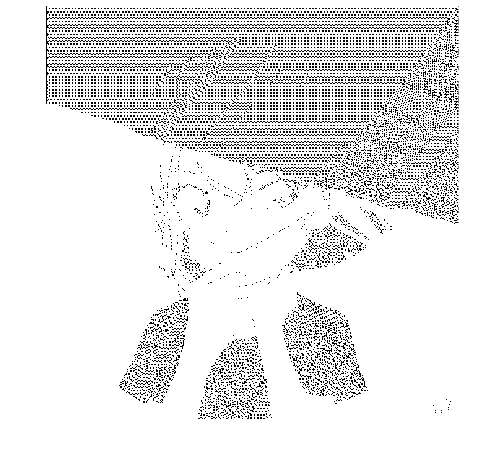

imshow(R_secret)

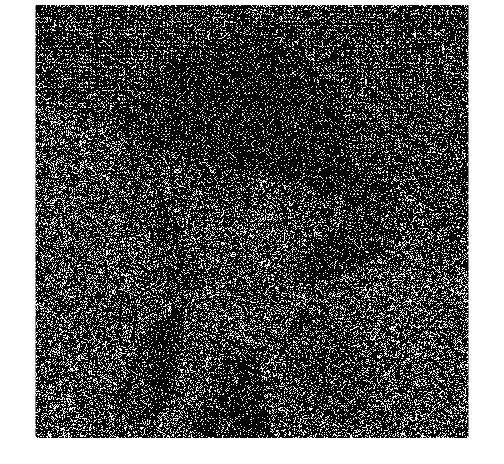

imshow(G_secret_2x)

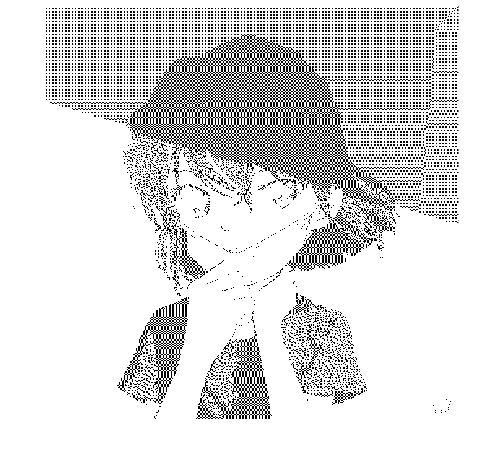

imshow(G_secret)

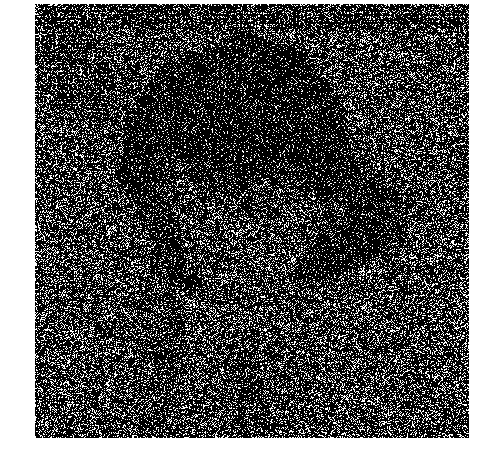

imshow(B_secret_2x)

imshow(B_secret)

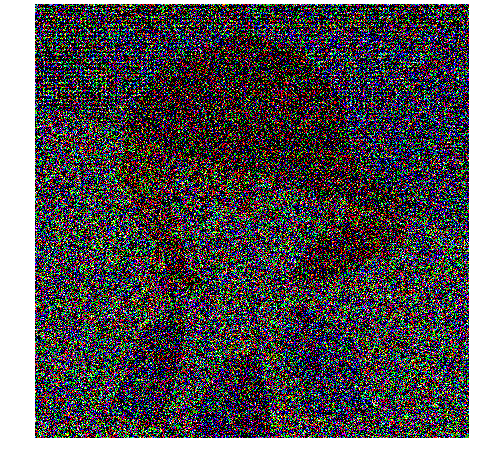

% 合成彩色图像
secret(:,:,1) = R_secret;
secret(:,:,2) = G_secret;
secret(:,:,3) = B_secret;
secret_2x(:,:,1) = R_secret_2x;
secret_2x(:,:,2) = G_secret_2x;
secret_2x(:,:,3) = B_secret_2x;

% Show Image
imshow(secret_2x)

imshow(secret)